## Set up

clc
clear
clf
rng(16);

### Preprocessing

FullSet = readtable("process_model\generated_data_take2\training\Noisy\measured_data_combined.csv");
X = FullSet(:,2:3);
X.f_LO_measured = FullSet.f_LO_measured;
X.f_LE_measured = FullSet.f_LE_measured;
X.c_RaffP_measured = FullSet.c_RaffP_measured;
X.c_RaffS_measured = FullSet.c_RaffS_measured;
X.c_BO_measured = FullSet.c_BO_measured;


X_N = normalize(X);

y = FullSet.fault_state;

rng('default'); % For reproducibility
cv = cvpartition(y, 'Holdout', 0.3); % 70% training, 30% testing
X_train = X_N(training(cv), :);
y_train = y(training(cv));
X_test = X_N(test(cv), :);
y_test = y(test(cv));


% Apply LDA for dimensionality reduction on the training data
num_components = 2; % Number of components in the reduced space
lda_model = fitcdiscr(X_train, y_train); % Fit the LDA model
[eigenvectors, eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, sorted_indices] = sort(diag(eigenvalues), 'descend');
projection_matrix = eigenvectors(:, sorted_indices(1:num_components));

% Project training and testing data onto the LDA components
X_train_reduced = table2array(X_train) * projection_matrix;
X_test_reduced = table2array(X_test) * projection_matrix;

lda_reduced = fitcdiscr(X_train_reduced, y_train);

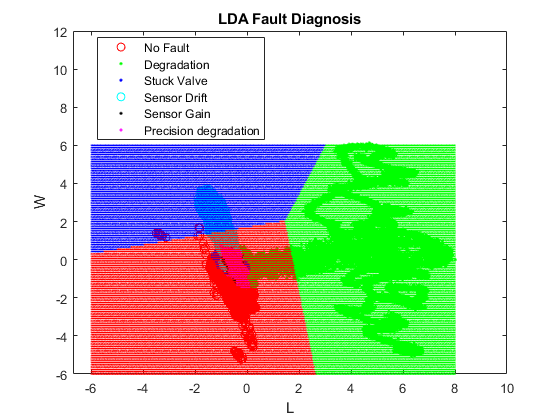


% Visualization of training data in the reduced dimensional space
gscatter(X_train_reduced(:, 1), X_train_reduced(:, 2), y_train, 'rgbckm', 'o..');
title('LDA Fault Diagnosis');
xlabel('LDA Component 1');
ylabel('LDA Component 2');

[L, W] = meshgrid(linspace(-6, 8, 500), linspace(-6,6,100)); ...
L = L(:);
W = W(:);
pred = lda_reduced.predict([L W]);
hold on;
h = gscatter(L, W, pred, 'rgbckm', '.', 0.1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
legend('No Fault', 'Degradation', 'Stuck Valve', 'Sensor Drift', 'Sensor Gain', 'Precision degradation');
hold off; 
print('process_model/generated_data_take2/training/Noisy/Results/LDA_visual', '-dpng', '-r600')


% Predict on the test data and calculate the confusion matrix
y_pred = predict(lda_reduced, X_test_reduced);
C = confusionmat(y_test, y_pred);
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

      102766           0           0          24           0           0
        8135       16916           0           0           0           0
        5867           0           0           1           0           0
        5489           0           0       13060           0           0
        1067           0           0           0           0           0
        2196           0           0           0           0           0



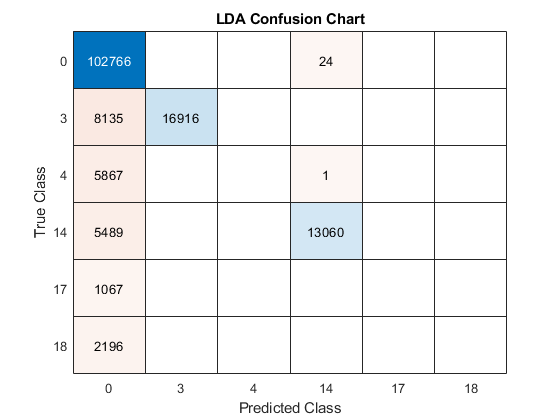


confusionchart(y_test, y_pred)
title('LDA Confusion Chart');
print('process_model/generated_data_take2/training/Noisy/Results/LDA_confchart', '-dpng', '-r600')

mean(y_pred == y_test)

ans = 0.8535

Predictions

[ldaPredClass, ldaPredPosterior] = predict(lda_reduced,X_test_reduced);
mean(ldaPredClass == y_test)

ans = 0.8535

50% threshold

sum(ldaPredPosterior(:,1) >= 0.5)

ans = 125205

sum(ldaPredPosterior(:,1) < 0.5)

ans = 30316

ldaPredPosterior(1:20,1).'

ans =     0.9073    0.9097    0.9081    0.9078    0.9057    0.9043    0.9052    0.9051    0.9062    0.9092    0.9081    0.8871    0.9011    0.8899    0.8903    0.8882    0.8889    0.8948    0.8896    0.8949


ldaPredClass(1:20,1).'

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% 90 %
sum(ldaPredPosterior(:,1) >= 0.9)

ans = 84625